## Multi_causality_with_graph

% Define coefficients  
a = [0, 0, -0.6, 0, 0, 0;  
     0.5, 0, 0, 0, 0, 0.8;  
    0, 0.7, -0.6, 0, 0, 0;  
     0, 0, 0, 0.7, 0.4, 0;  
     0, 0, 0, 0.2, 0, 0.7;  
     0, 0, 0, 0, 0, -0.5];  
b = [0.1; 0.7; 0.5; 0.2; 0.8; 0.3];  
  
% Initialize parameters  
M = 6;  
N = 100001;  
xx = zeros(N, M);  
xx(1, :) = [0.4, 0.5, 0.6, 0.7, 0.6, 0.7];  
  
% Generate data  
for i = 1:(N-1)  
    xx(i+1, :) = a * xx(i, :)' + b + randn( M,1); % Note the transpose ' and the use of randn  
end  
xx = xx(10001:end, :)';

% Call the function  
IF = multi_causality_all(xx); % Note the transpose ' to match dimensions

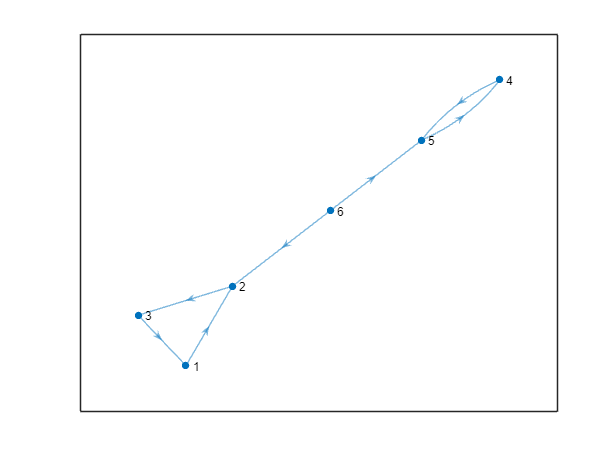

a = IF.nIF;  
b = IF.p;  
E=a+0;
E(~(abs(a)>0.001&b<0.01))=0;


%E=abs(T)>err&abs(a)>0.00001;
s=[];t=[];
for i=1:6
    for j=1:6
        if i~=j&E(i,j)~=0
            s=[s j];
            t=[t i];
        end
    end
end


G=digraph(s,t);
plot(G,'Layout','force')

## Time delay

addpath('C:\Users\Yinen\OneDrive\文档\GitHub\LKIF\IF_3.1.1\matlab')
% Generate data  
n = 20000;  
p = 5;  
xx = zeros(n, p);  
xx(1:4, :) = randn(4, p); % Use randn instead of numpy.random.normal  
  
for i = 5:(n-1)  
    xx(i+1, 1) = -0.95*sqrt(2)*xx(i, 1) - 0.9025*xx(i-1, 1) + randn();  
    xx(i+1, 2) = 0.5*xx(i-1, 1) + randn();  
    xx(i+1, 3) = -0.4*xx(i-2, 1) + randn();  
    xx(i+1, 4) = -0.5*xx(i-1, 1) + 0.25*sqrt(2)*xx(i, 4) + 0.25*sqrt(2)*xx(i, 5) + randn();  
    xx(i+1, 5) = -0.25*sqrt(2)*xx(i, 4) + 0.25*sqrt(2)*xx(i, 5) + randn();  
end  
  
% Process data  
xx1 = zeros(n-1000, 7);  
xx1(:, 1:5) = xx(1001:end, :);  
xx1(:, 6) = xx(1000:end-1, 1); % X6 = X0[t-1]  
xx1(:, 7) = xx(999:end-2, 1); % X7 = X0[t-2]  
  
% Assume multi_causality_est is a function that exists in MATLAB or is defined below  
% Here we define a simple placeholder function  

  
% Call the function  
IF = multi_causality_all(xx1'); % Note the transpose ' to match dimensions  
  
% Exclude fake causality  
a = IF.nIF;  
b = IF.p;  
a(6:end, :, :) = 0; % MATLAB indexing starts at 1  
b(6:end, :,:) = 1;  



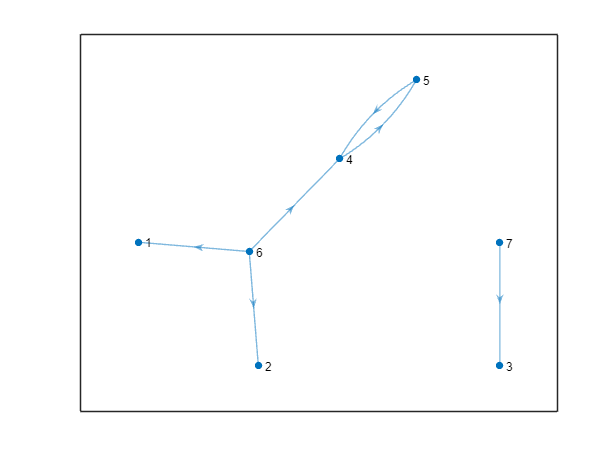

E=a+0;
E(~(abs(a)>0.001&b<0.01))=0;


%E=abs(T)>err&abs(a)>0.00001;
s=[];t=[];
for i=1:7
    for j=1:7
        if i~=j&E(i,j)~=0
            s=[s j];
            t=[t i];
        end
    end
end


G=digraph(s,t);
plot(G,'Layout','force')

disp('{x6(t)}={x1(t-1)}')

{x6(t)}={x1(t-1)}


disp('{x7(t)}={x1(t-2)}')

{x7(t)}={x1(t-2)}
